clear 

%a)

fprintf("Subamortiguada (0 < E < 1)")

Subamortiguada (0 < E < 1)


E=0.5;       %coeficiente de amortiguamiento
wn=1;       %frecuencia natural no amortiguada
wd=wn*sqrt(1-E^2) %frecuencia de amortiguamiento

wd = 0.8660

sigma=E*wn

sigma = 0.5000



n=[wn^wn];
d=[1 2*E*wn wn^2];

fdt=tf(n,d)


fdt =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



step(fdt) 
hold on 


%b)

tr=(pi - atan(wd/sigma)) / wd %t de subida

tr = 2.4184

scatter(tr,1,'g')

tp=pi/wd %t de pico

tp = 3.6276

scatter(tp,1.16,'b')

ts=pi/sigma %t de establecimiento

ts = 6.2832

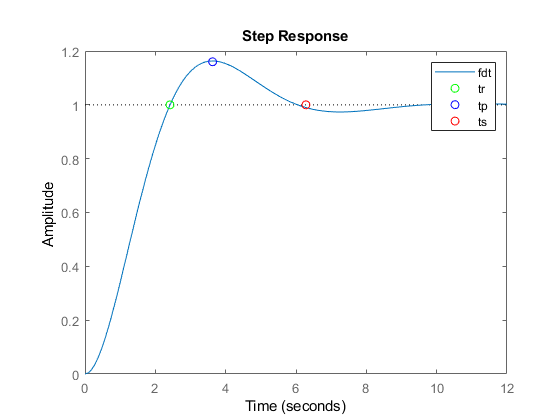

scatter(ts,1,'r')

legend('fdt','tr','tp','ts')
hold off


Mp = exp(-(sigma/wd)*pi)*100 %sobreoscilacion maxima

Mp = 16.3034


Mp = exp((-pi*E)/sqrt(1-E^2)) * 100

Mp = 16.3034